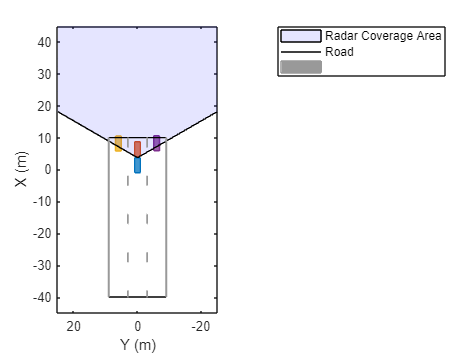

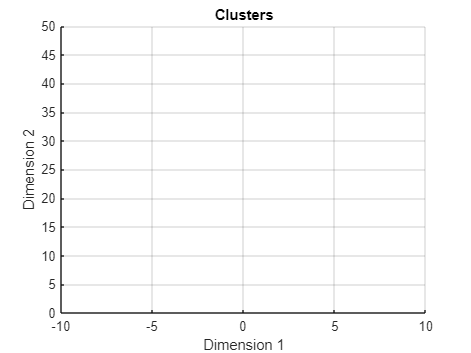

%Close all previous displays
close all

% Create the drivingScenario object and ego car
[scenario, egoVehicle] = createDrivingScenario;

% Create all the sensors
sensor = createSensor(scenario);

%Create birds eye plot
bep = birdsEyePlot('XLim',[-45 45],'YLim',[-25 25]);
hold on

%Create coverage area plotter
caPlotter = coverageAreaPlotter(bep, 'DisplayName','Radar Coverage Area','FaceColor','b');
plotCoverageArea(caPlotter,sensor.MountingLocation(1:2),sensor.RangeLimits(2),sensor.MountingAngles(1),sensor.FieldOfView(1));

%Create road boundaries plotter
lbPlotter = laneBoundaryPlotter(bep,'DisplayName','Road');
lmPlotter = laneMarkingPlotter(bep);

%Create vehicle plotter
olPlotter = outlinePlotter(bep);

plot(scenario);
hold on;

%Create clusteringDBSCAN object
clusterer = clusterDBSCAN('EpsilonSource','Property','Epsilon',4,'MinNumPoints',3,'EnableDisambiguation',false);

allData = struct('Time', {}, 'ActorPoses', {}, 'ObjectDetections', {});
running = true;
while running

    % Generate the target poses of all actors relative to the ego vehicle
    poses = targetPoses(egoVehicle);
    time  = scenario.SimulationTime;

    % Generate detections for the sensor
    [objectDetections, isValidTime] = sensor(poses, time);
    numObjects = length(objectDetections);
    objectDetections = objectDetections(1:numObjects);

    [lmv,lmf] = laneMarkingVertices(egoVehicle);
    plotLaneMarking(lmPlotter,lmv,lmf)
    rbEgoVehicle = roadBoundaries(egoVehicle);
    plotLaneBoundary(lbPlotter,rbEgoVehicle)


    [olPosition,olYaw,olLong,olWidth,olOriginOffset,olColor] = targetOutlines(egoVehicle);
    plotOutline(olPlotter,olPosition,olYaw,olLong,olWidth,'OriginOffset',olOriginOffset,'Color',olColor);

    if numObjects
        objectData = zeros(numObjects, 4);

        for i = 1:numObjects
            objectData(i, :) = [objectDetections{i,1}.Measurement(1)+egoVehicle.Position(1);objectDetections{i,1}.Measurement(2)+egoVehicle.Position(2);objectDetections{i,1}.Measurement(4);objectDetections{i,1}.Measurement(5)];
        end

        clustererPlot = clusterer(objectData(:, 1:2));

        % Plot data points with clusterDBSCAN plot function
        plot(clusterer,objectData(:, 1:2),clustererPlot);
        xlim([-10 10]);  % Set x-axis limits
        ylim([0 50]);  % Set y-axis limits

        % Get the unique cluster labels
        clusterLabels = unique(clustererPlot);

    end

    % Aggregate all detections into a structure for later use
    if isValidTime
        allData(end + 1) = struct( ...
            'Time',       scenario.SimulationTime, ...
            'ActorPoses', actorPoses(scenario), ...
            'ObjectDetections', {objectDetections});
    end

    % Advance the scenario one time step and exit the loop if the scenario is complete
    running = advance(scenario);
end

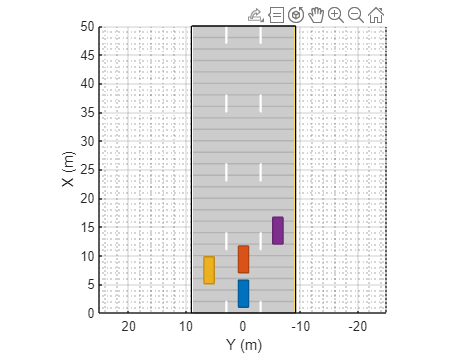


% Restart the driving scenario to return the actors to their initial positions.
restart(scenario);


% Release the sensor object so it can be used again.
release(sensor);
%%----------------------------------------------------------------------------------------------


function sensor = createSensor(scenario)
% createSensors Returns all sensor objects to generate detections

% Assign into each sensor the physical and radar profiles for all actors
profiles = actorProfiles(scenario);
sensor = drivingRadarDataGenerator('SensorIndex', 1, ...
    'MountingLocation', [3.7 0 0.2], ...
    'RangeLimits', [0 100], ...
    'TargetReportFormat', 'Detections', ...
    'FieldOfView', [120 5], ...
    'Profiles', profiles);
end
%%----------------------------------------------------------------------------------------------
function [scenario, egoVehicle] = createDrivingScenario
% createDrivingScenario Returns the drivingScenario defined in the Designer

% Construct a drivingScenario object.
scenario = drivingScenario('StopTime',4);

% Add all road segments
roadCenters = [50 0 0;
    0 0 0];
laneSpecification = lanespec(3, 'Width', 6);
road(scenario, roadCenters, 'Lanes', laneSpecification, 'Name', 'Road');

% Add the ego vehicle
egoVehicle = vehicle(scenario, ...
    'ClassID', 1, ...
    'Position', [2 0 0], ...
    'Mesh', driving.scenario.carMesh, ...
    'Name', 'Car');
waypoints = [2 0 0;
    3 0 0;
    40 0 0];
speed = [0;15;15];
waittime = [0.5;0;0];
trajectory(egoVehicle, waypoints, speed, waittime);

% Add the non-ego actors
car1 = vehicle(scenario, ...
    'ClassID', 1, ...
    'Position', [8 0 0], ...
    'Mesh', driving.scenario.carMesh, ...
    'Name', 'Car1');
waypoints = [8 0 0;
    40 0 0;
    45 0 0];
speed = [15;15;0];
waittime = [0;0;0];
trajectory(car1, waypoints, speed, waittime);

car2 = vehicle(scenario, ...
    'ClassID', 1, ...
    'Position', [6.1 6 0], ...
    'Mesh', driving.scenario.carMesh, ...
    'Name', 'Car2');
waypoints = [6.1 6 0;
    47 6 0];
speed = [22;22];
waittime = [0;0];
trajectory(car2, waypoints, speed, waittime);

car3 = vehicle(scenario, ...
    'ClassID', 1, ...
    'Position', [13 -6 0], ...
    'Mesh', driving.scenario.carMesh, ...
    'Name', 'Car3');
waypoints = [13 -6 0;
    47 -6 0];
speed = [15;15];
waittime = [0;0];
trajectory(car3, waypoints, speed, waittime);
end
